## CurrentPosition Points

Real_Points = out.realPosition.signals.values(:, 1:2);
x_CurrentPos = Real_Points(:, 1);
y_CurrentPos = Real_Points(:, 2);

## Reference Waypoints

Reference_Waypoints = out.Trajectory_Waypoints.signals.values(:, :, 1);
x_ModPoints = Reference_Waypoints(:, 1);
y_ModPoints = Reference_Waypoints(:, 2);

## Gradient

gradient_vector = zeros(length(Reference_Waypoints), 1);
gradient_vector(1, 1) = 0;

for i = 2:length(Reference_Waypoints)
    gradient_vector(i) = (Reference_Waypoints(i, 2) - Reference_Waypoints(i-1, 2)) / (Reference_Waypoints(i, 1) - Reference_Waypoints(i-1, 1));
end

## Lane Points

Lane_Points_L = zeros(length(Reference_Waypoints), 2);
Lane_Points_R = zeros(length(Reference_Waypoints), 2);

for i = 1: length(Reference_Waypoints)
    Lane_Points_R(i, 1:2) = [Reference_Waypoints(i, 1) - 1.6*sind(gradient_vector(i)), Reference_Waypoints(i, 2) - 1.6*cosd(gradient_vector(i))];
    Lane_Points_L(i, 1:2) = [Reference_Waypoints(i, 1) + 1.6*sind(gradient_vector(i)), Reference_Waypoints(i, 2) + 1.6*cosd(gradient_vector(i))];
end

Lane_L_X = Lane_Points_L(:, 1);
Lane_L_Y = Lane_Points_L(:, 2);

Lane_R_X = Lane_Points_R(:, 1);
Lane_R_Y = Lane_Points_R(:, 2);

## INS (Drifted) Waypoints

INS_Points = out.insPosition.signals.values(:, 1:2);
x_INSP = INS_Points(:, 1);
y_INSP = INS_Points(:, 2);
INS_Pt = [x_INSP, y_INSP];

## Plots & Figures

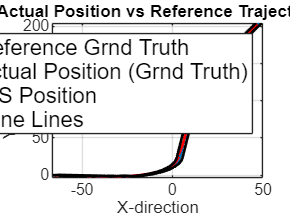

figure;

p1 = plot(-y_ModPoints, x_ModPoints, 'LineWidth', 1.5); % Reference Waypoints
hold on

p2 = plot(-y_CurrentPos, x_CurrentPos, '-m', 'LineWidth', 1.5); % Current Grnd Truth
hold on

p3 = plot(x_INSP, y_INSP, '-r', 'LineStyle','-', 'LineWidth', 1.5); % INS (Drifted)
hold on

p_LaneLeft = plot(-Lane_L_Y, Lane_L_X, '-k', 'LineStyle','-', 'LineWidth', 1.5); % Left Lane Lines
hold on

p_LaneRight = plot(-Lane_R_Y, Lane_R_X, '-k', 'LineStyle','-', 'LineWidth', 1.5); % Right Lane Lines
hold on

legend('Reference Grnd Truth', 'Actual Position (Grnd Truth)', 'INS Position', 'Lane Lines');
% legend('Reference Grnd Truth', 'Actual Position (Grnd Truth)');

% xlim([-25 -10])
% ylim([-97 100])
fontsize(legend, 12, 'points')
title('Actual Position vs Reference Trajectory')
xlabel('X-direction')
ylabel('Y-direction')

grid on

plot(1:1:length(out.fault_flag.signals.values), out.fault_flag.signals.values, 'LineWidth', 2);
grid on
xlabel('Time')
ylabel('Fault Flag')


# `ANALYSIS`

## Cross-track Error between INS Position and Waypoints

% [INS2Ref_Error, index] = (sqrt((x_INSPos(32) - x_ModPoints).^2 + (y_INSPos(32) - y_ModPoints).^2), 4);

[INS2Ref_Error, index] = min(sqrt((x_INSPos(32) - x_ModPoints).^2 + (y_INSPos(32) - y_ModPoints).^2));
Distance2Ref = sqrt((INS_Pt(1, 1) - Reference_Waypoints(:, 1)).^2 + (INS_Pt(1, 2) - Reference_Waypoints(:, 1)).^2);
disp(Distance2Ref)

## Manipulate (Repeated Points Deletion)

idx = x_CurrentPos < 0;

hold on
count = 0;
myplot = plot(-y_CurrentPos(idx),x_CurrentPos(idx),'*k');

for ind = idx
    datatip(myplot, -y_CurrentPos(idx), x_CurrentPos(idx));
    count = count + 1;
end
realPos_xy = zeros(length(real_xy), 2);
realPos_xy(1, 1:2) = real_xy(1, 1:2);

plot(realPos_xy(:, 1), realPos_xy(:, 2), '-r', 'LineWidth', 0.5);

## Difference

diff = zeros(length(real_xy), 2);
diff(1, 1:2) = real_xy(1, 1:2);

for j = 2:length(diff)
    diff(j, 1:2) = real_xy(j, 1:2) - real_xy(j-1, 1:2);
end

disp(diff(1:20, 1:2))

realPos_xy = zeros(length(real_xy), 2);
count = 2;
for len = 2:length(diff)
    if diff(len, 1) >= 0
        realPos_xy(count, 1:2) = real_xy(len, 1:2);
        count = count + 1;
    end
end
% for i = 1:length(realest_xy)
%     if floor(real_xy(1)) ~= -22
%         realest_xy(i, :) = real_xy(i, :);
%     end
% end

## Close Figures

close;

## Metrics, Error Calculations

error = [sqrt((x_RefPoints(110) - x3).^2 + (y_RefPoints(110) - y3).^2)];